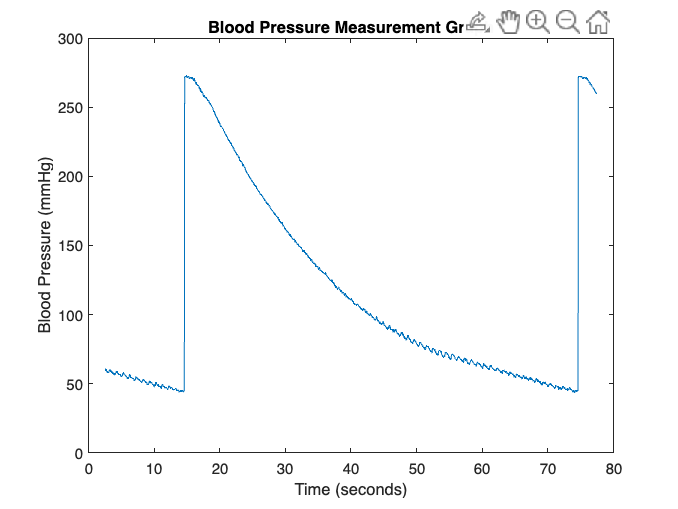

clear; % clears memory - useful if you run many scripts in the same session
clf;

%take in data from csv file
tname='BPdata.csv'; % <-input your data file's name! test2.csv was exported from O-scope software with a line of headers
datatable  = readtable(tname);%makes data table with headers

%interpret data as times and voltages
time1  = datatable.t1; % stores the t1 column of data in a variable called time1 
time1 = time1+40;
V1    = datatable.ch1; % stores the ch1 column of data in a variable called V1   
time2    = datatable.t2; %stores the t2 column of data in a variable called time2 
V2 = datatable.ch2; %stores the ch2 column of data in a variable called V2  

%V1(1:243) = V1(1:243) + 0.35;
%V1(244:end) = V1(244:end) - 1.75;



BP = (((V1./5) - 0.04) / 0.018) * (760/101.325); %transfer function


%plot (you can change this section to suit your plotting needs!)
%plot(time1(1:400),BP(1:400)) %plots first channel
plot(time1,BP)
xlabel('Time (seconds)'); % add x axis label 
%ylim([0 140])
ylabel('Blood Pressure (mmHg)'); % add y axis label 
title('Blood Pressure Measurement Graph');